# Parameter Definition for Selected Methods on Biologic Potentiostat

This file contains templates of structured variables for defining particular techniques. All these techniques have been tested by the author.

The structures define parameters specific for each particular technique. Two structures exist for each technique (except OCV, this technique is single-step):

	(i) technique parameters - these parameters are static over all technique steps

	(ii) step parameters - these parameters are unique to each technique step. Some of these parameters can be modified on the fly, some not (see manual)

See the manual "EC-Lab® Development Package User Guide" for details.

## Probe hardware parameters

These parameters define how the probes are connected. They do not change during whole measurement and are technique independent. Setting is possible on VMP-300 series only.

ProbeConf = struct( ...
	'Connection', 0, ...			% 0 .. standard, 1 .. CE to ground, 2 .. WE to ground, 3 .. High voltage
	'Mode', 1);						% 0 .. grounded, 1 .. floating

## Open Circuit Voltage (OCV)

% Parameters for OCV technique
TechParamsOCV = struct( ...
	'technique', 'OCV', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "AUTO", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, AUTO, KEEP = from previous method)
	'Bandwidth', 8, ...				% BW number for loopback (1, 2, ... 9, BL.KEEP)
	'Rest_time_T', 10, ...			% duration of measurement (seconds)
	'Record_every_dT', 0.1, ...		% sampling period (seconds, def = 1)
    'Record_every_dE', 0.01);		% voltage increment that trigerrs new sample (Volts); Inf = ignore

## Constant Voltage Techniques

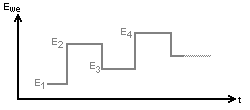

### Chrono-Amperometry Technique (CA)

TechParamsCA = struct( ...
	'technique', 'CA', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "AUTO", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, AUTO, KEEP = from previous method);
	...								% AUTO not allowed for current source methods
	'Bandwidth', 8, ...				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)
	'Record_every_dT', 1, ...		% sampling period (seconds, def = 1)
	'Record_every_dI', Inf, ...		% current increment that triggers new sample (Amps); Inf = ignore
    'Step_number', 0, ...			% number of steps - 1
    'N_Cycles', 0);					% number of times the technique is repeated - 1

StepParamsCA = struct( ...
	'Voltage_step', 1, ...			% voltage (V)
	'vs_initial', false, ...		% voltage is relative to the final voltage of the previous technique
	'Duration_step', 10, ...		% max step duration (s); step ends with duration or with test condition - what comes first
	);

### Chrono-Amperometry Technique with Limits (CALIMIT)

TechParamsCALIMIT = struct( ...
	'technique', 'CALIMIT', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "AUTO", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, AUTO, KEEP = from previous method)
	'Bandwidth', 8, ...				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)
	'Record_every_dT', 1, ...		% sampling period (seconds, def = 1)
	'Record_every_dI', Inf, ...		% current increment that triggers new sample (Amps); Inf = ignore
    'Step_number', 0, ...			% number of steps - 1
    'N_Cycles', 0);					% number of times the technique is repeated - 1

StepParamsCALIMIT = struct( ...
	'Voltage_step', 1, ...			% voltage (V)
	'vs_initial', false, ...		% voltage is relative to the final voltage of the previous technique
	'Duration_step', 10, ...		% max step duration (s); step ends with duration or with test condition - what comes first
	'Test1_Config', 101, ...		% binary: 0bVV|S|L|A; VV = variable (00 = voltage, 01 = AUX1, 10 = AUX2, 11 = current); Sign (0 = "<", 1 = ">");
	...								% Logic (0 = OR, 1 = AND); Active (1 = active); example: Current > 0.5 A: 0B11|001|x|1 = 101, other conditions inactive
	...								% (Test1 AND/OR Test2) AND/OR Test3; next condition is tested only if active
	'Test1_Value', 0.5, ...			% condition value (0.5 A in example above)
	'Test2_Config', 0, ...
	'Test2_Value', 0.0, ...
	'Test3_Config', 0, ...
	'Test3_Value', 0.0, ...
	'Exit_Cond', 2 ...				% exit condition; 0 = next step, 1 = next technique, 2 = stop
	);

## Constant Current Techniques

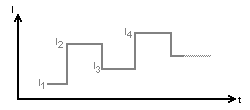

### Chrono-Potentiometry Technique (CP)

TechParamsCP = struct( ...
	'technique', 'CP', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "1A", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, KEEP = from previous technique)
    'Bandwidth', 8, ...				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)
	'Record_every_dT', 0.1, ...		% sampling period (seconds, default = 1)
	'Record_every_dE', 0.01, ...	% voltage increment that triggers new sample (Volts); Inf = ignore
    'Step_number', 0, ...			% number of steps - 1
    'N_Cycles', 0);					% number of times the technique is repeated - 1

StepParamsCP = struct( ...
	'Current_step', 0, ...			% current (Amps)
	'vs_initial', false, ...		% current is relative to the final current of the previous technique
	'Duration_step', 100, ...		% maximum duration of the step (seconds)
	);

### Chrono-Potentiometry Technique with Limits (CPLIMIT)

TechParamsCPLIMIT = struct( ...
	'technique', 'CPLIMIT', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "1A", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, KEEP = from previous technique)
    'Bandwidth', 8, ...				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)
	'Record_every_dT', 0.1, ...		% sampling period (seconds, default = 1)
	'Record_every_dE', 0.01, ...	% voltage increment that triggers new sample (Volts); Inf = ignore
    'Step_number', 0, ...			% number of steps - 1
    'N_Cycles', 0);					% number of times the technique is repeated - 1

StepParamsCPLIMIT = struct( ...
	'Current_step', 0, ...			% current (Amps)
	'vs_initial', false, ...		% current is relative to the final current of the previous technique
	'Duration_step', 100, ...		% maximum duration of the step (seconds)
	'Test1_Config', 0, ...			% 0bVV|S|L|A; VV = variable (00 = voltage, 01 = AUX1, 10 = AUX2, 11 = current); Sign (0 = "<", 1 = ">");
	...								% Logic (0 = OR, 1 = AND); Active (1 = active); example: Voltage > bias V: 0B00|001|x|1 = 5, other conditions inactive
	...								% voltage > bias: 0B00|001|x|1 = 5; voltage < bias: 0B00|000|x|1 = 1; 
	'Test1_Value', 0, ...			% condition (voltage) value
	'Test2_Config', 0, ...
	'Test2_Value', 0.0, ...
	'Test3_Config', 0, ...
	'Test3_Value', 0.0, ...
	'Exit_Cond', 0 ...				% exit condition; 0 = next step, 1 = next technique, 2 = stop measurement completely
	);

## Sinusoidal techniques

### Large Amplitude Sinusoidal Voltammetry (LASV)

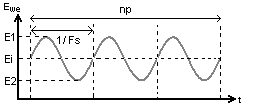

TechParamsLASV = struct( ...
    'technique', 'LASV', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "100mA", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, AUTO, KEEP = from previous step)
    'Bandwidth', 8, ...				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)
	'Ei', 0, ...					% initial potential (Volts)
	'Ei_vs_initial', false, ...		% (default = false)
    'Step_number', 0, ...			% number of steps - 1; max = 19
    'N_Cycles', 0);					% number of times the technique is repeated - 1

StepParamsLASV = struct( ...
	'Fs', 0.1, ...					% frequency (Hz, default = 1)
	'E1', 1, ...					% high peak potential (Volts)
	'E1_vs_initial', false, ...		% voltage is relative to the final voltage of the previous technique (default = false)
	'E2', 0, ...					% low peak potential (Volts)
	'E2_vs_initial', false, ...		% voltage is relative to the final voltage of the previous technique (default = false)
	'Period_number', 1, ...			% number of signal periods per step (integer, default = 0)
	'Record_every_dT', 0.1, ...		% sampling period (seconds, def = 1)
	'Record_every_dI', Inf);		% current increment that triggers new sample (Amps); Inf = ignore

### Constant Amplitude Sinusoidal micro Galvano polarization technique (CASG)

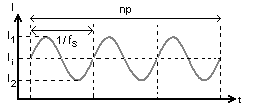

TechParamsCASG = struct( ...
    'technique', 'CASG', ...
	'E_Range', "5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
	'I_Range', "100mA", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, KEEP = from previous step); AUTO not allowed
    'Bandwidth', 8, ...				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)
	'Ii', 0, ...					% initial current (Amp)
	'Ii_vs_initial', false, ...		% current is relative to the final current of the previous technique (default = false)
    'Step_number', 0, ...			% number of steps - 1; max = 19
    'N_Cycles', 0);					% number of times the technique is repeated - 1

StepParamsCASG = struct( ...
	'Fs', 1, ...					% frequency (Hz, def = 1)
	'I1', 0.1, ...					% high peak current (Amp)
	'I1_vs_initial', false, ...		% current is relative to the final current of the previous technique (default = false)
	'I2', -0.1, ...					% low peak current (Amp)
	'I2_vs_initial', false, ...		% current is relative to the final current of the previous technique (default = false)
	'Period_number', 1, ...			% number of signal periods per step (integer, default = 0)
	'Record_every_dT', 1, ...		% sampling period (seconds, default = 1)
	'Record_every_dE', Inf);		% voltage increment that triggers new sample (Volts); Inf = ignore

## Impedance spectroscopy

### Potentio Electrochemical Impedance Spectroscopy technique (PEIS)

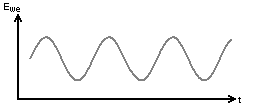

TechParamsPEIS = struct( ...
    'technique', 'PEIS', ...
	'E_Range', "2.5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
    'I_Range', "AUTO", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, AUTO, KEEP = from previous step)
	...								% AUTO is allowed for I_Range but makes troubles; not recommended
	'Bandwidth', 8);				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)

StepParamsPEIS = struct( ...
	'Initial_Voltage_step', 1, ...	% bias voltage (V)
	'vs_initial', false, ...		% bias voltage is relative to the final voltage of the previous technique
	'Duration_step', 5, ...			% duration of initial phase that sets bias voltage (s)
	'Record_every_dT', 0.1, ...		% sampling period (seconds, def = 1) during initial phase
	'Record_every_dI', Inf, ...		% current increment that triggers new sample (Amps); Inf = ignore
	'Initial_frequency', 0.1, ...	% starting frequency for sweeping (Hz)
	'Final_frequency', 0.0001, ...	% final frequency (Hz); can be lower than starting frequency (sweep frequency down)
	'sweep', false, ...				% true = linear frequency distribution, false = logarithmic
	'Amplitude_Voltage', 0.01, ...	% measuring AC voltage amplitude (V)
	'Frequency_number', 21, ...		% total number of frequencies
	'Average_N_times', 5, ...		% how many repeat times for averaging
	'Correction', true, ...			% drift correction
	'Wait_for_steady', 1);			% number of periods to wait before measurement starts (single precision)

### Galvano Electrochemical Impedance Spectroscopy technique (PEIS)

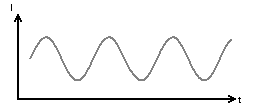

TechParamsGEIS = struct( ...
    'technique', 'GEIS', ...
	'E_Range', "2.5V", ...			% ±voltage measuring range (2.5V, 5V, 10V, AUTO)
    'I_Range', "1mA", ...			% ±current measuring range (100pA, 1nA, ..., 100mA, 1A, BOOSTER, KEEP = from previous step); AUTO Not allowed
	'Bandwidth', 8);				% bandwidth number for loopback (1, 2, ... 9, BL.KEEP)

StepParamsGEIS = struct( ...
	'Initial_Current_step', 0, ...	% bias current (A)
	'vs_initial', false, ...		% bias current is relative to the final current of the previous technique
	'Duration_step', 5, ...			% duration of initial phase setting bias current (s)
	'Record_every_dT', 0.1, ...		% sampling period (seconds, def = 1) during initial phase
	'Record_every_dE', Inf, ...		% voltage increment that triggers new sample (V); Inf = ignore
	'Initial_frequency', 0.004, ...	% starting frequency for sweeping (Hz)
	'Final_frequency', 0.00004, ...	% final frequency (Hz); can be lower than starting frequency (sweep frequency down)
	'sweep', false, ...				% true = linear frequency distribution, false = logarithmic
	'Amplitude_Current', 0.001, ...	% measuring AC current amplitude (A)
	'Frequency_number', 21, ...		% total number of frequencies
	'Average_N_times', 2, ...		% how many repeat times for averaging
	'Correction', false, ...		% drift correction
	'Wait_for_steady', 1);			% number of periods to wait before measurement starts (single precision)
